clear; close all;

# Kinodynamic Motion Planning

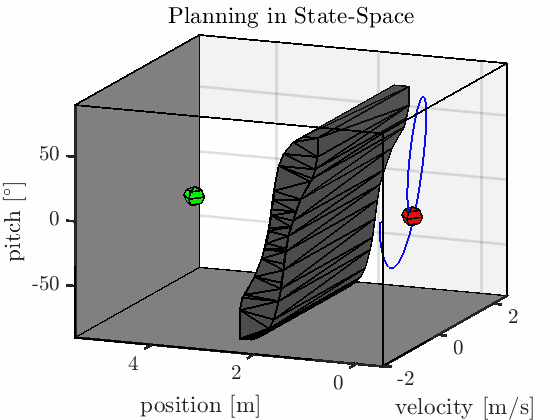

### Setting up the State-Space World

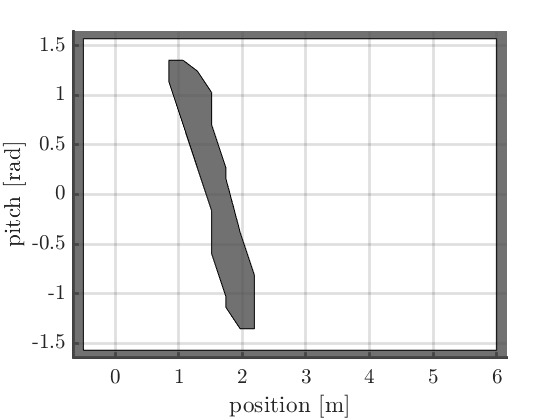

% State-Space boundaries
pitch_max             = deg2rad(90);
pitch_min             = deg2rad(-90);
pitch_velocity_max    = 2*pi;
pitch_velocity_min    = -2*pi;
position_max          = 6;
position_min          = -0.5;
position_velocity_max = 2;
position_velocity_min = -2;
xmax = [pitch_max; pitch_velocity_max; position_max; position_velocity_max];
xmin = [pitch_min; pitch_velocity_min; position_min; position_velocity_min];
% Action-Space boundaries
torque_max = 2;
torque_min = -2;
% State to configuration mapping
x2y_func = @twipr_x2y;      

% Setup the State-Space world 
statespace = CKinodynamicConfigWorld(xmax, xmin, torque_max, torque_min, x2y_func);
% Load our obstacle polygon
load('1_Data/obstacle.mat');
% Add the obstacle to our world
statespace.addObstacle(obstacle_polygon);
% Let's draw the world
figure;
statespace.draw();

### Local Motion Planning

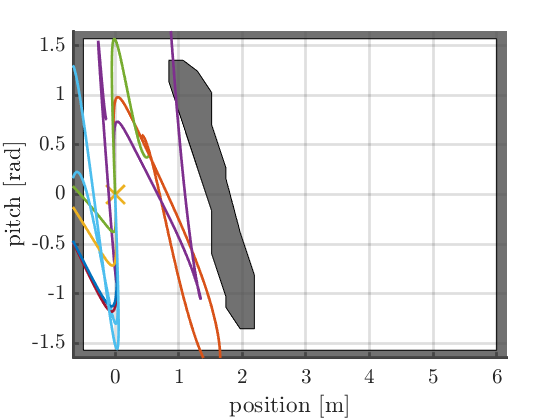

% Load TWIPR open-loop dynamic model to be used for local motion planning
twipr_open_loop_model = load("1_Data\twipr_ol_dynamics.mat");
% Function to forward simulate the twipr dynamics to determine state trajectories that result from the planned input trajectories (does not have to use the
% same model as the Local Motion Planning)
forward_sim_func      = @(x, u)forward_sim(x, u, twipr_open_loop_model.A, twipr_open_loop_model.B); 

% Maximum number of samples per LMP
Nmax = 250;
% Setup the local motion planning
[ANc,RIc] = lmp_precompute(Nmax, twipr_open_loop_model.A, twipr_open_loop_model.B); % Can be removed
% LMP function
% lmp_func is a function handle which covers all parameters but xI and xG
% returns input trajectory u between two local goals
lmp_func = @(xI, xG)lmp_time_opt_xcon_precomp(xI, xG,...
                                              torque_max, torque_min,...
                                              Nmax,...
                                              ANc, RIc,...
                                              twipr_open_loop_model);

% Let's do some LMP
% Initial State
xI = [0; 0; 0; 0];
plotConfiguration(xI([1,3]));
% Let's do some LMP to random local goal states
for k = 1:10
    x_local_goal = randn(4,1);              % random local goal in state space 
    u = lmp_func(xI, x_local_goal);         % u trajectory between 2 local goals
    X = forward_sim(xI, u, twipr_open_loop_model.A, twipr_open_loop_model.B);   % state trajectory between local goals
    plotStateTrajectoryInCSpace(X);         % plot state trajectory in c-space
end

### Exploration

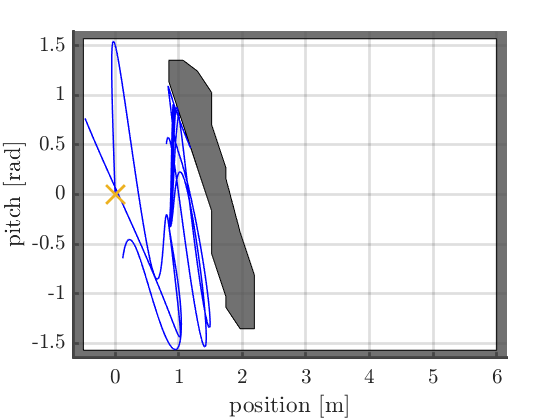

% Initialize RNG-Seed
rng(2);
% Distance function in state space
distance_func    = @twipr_state_distance;   % cost function to evaluate "distance" between local goals
% Number of RRT-Iterations 
K = 50;
% run kinodynamic exploration. returns kinodynamic RRT tree in form of the
% root node xI and all children nodes
% which represent up to 50 vertexes. each vertex connects 2 local goals
% in state space X with a fitting input trajectory U
tree = kinodynamic_exploration(statespace, xI, K, lmp_func, forward_sim_func, x2y_func, distance_func);
% Plot Results
figure;
statespace.draw();
tree.draw('blue');              % draw whole tree in c-space
plotConfiguration(xI([1,3]));   % draw initial node in c-space

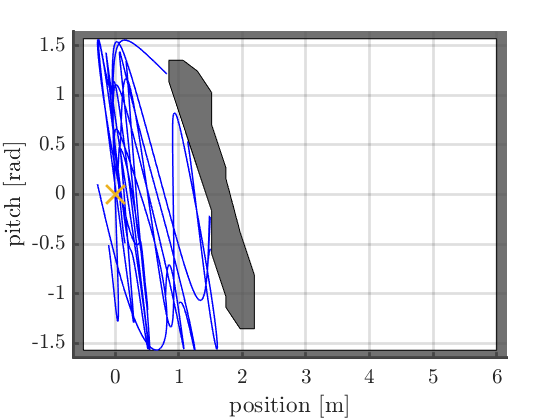


% Repeat with more RRT-Iterations
K = 150;
tree = kinodynamic_exploration(statespace, xI, K, lmp_func, forward_sim_func, x2y_func, distance_func);
% Plot Results
figure;
statespace.draw();
tree.draw('blue');
plotConfiguration(xI([1,3]));

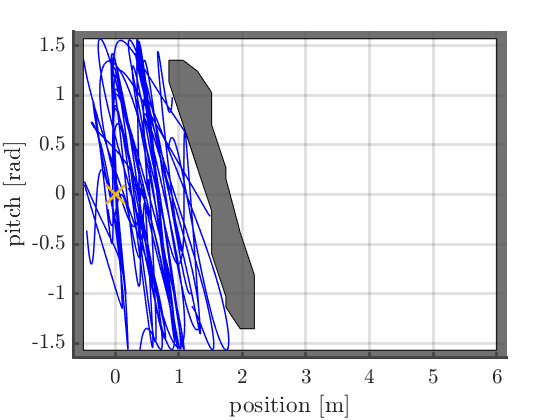


% and some more ...
K = 250;
tree = kinodynamic_exploration(statespace, xI, K, lmp_func, forward_sim_func, x2y_func, distance_func);
% Plot Results
figure;
statespace.draw();
tree.draw('blue');
plotConfiguration(xI([1,3]));

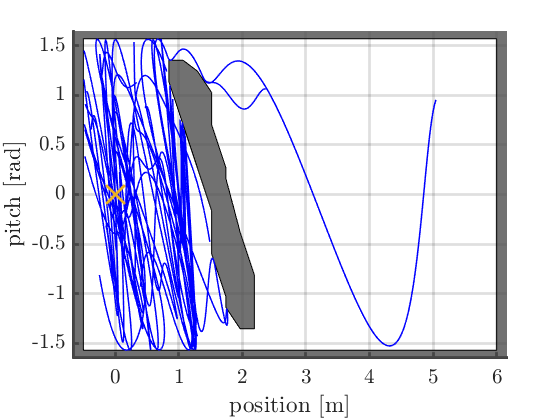



% and even more ...
K = 500;
tree = kinodynamic_exploration(statespace, xI, K, lmp_func, forward_sim_func, x2y_func, distance_func);
% Plot Results
figure;
statespace.draw();
tree.draw('blue');
plotConfiguration(xI([1,3]));

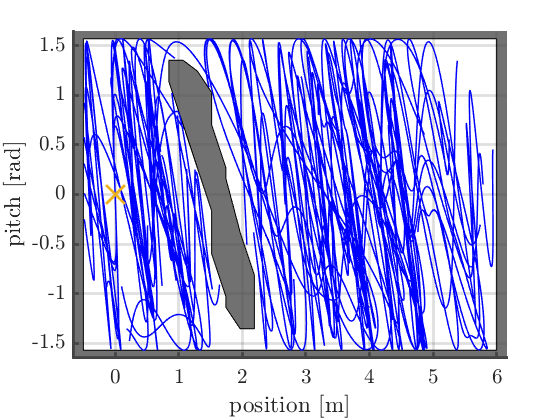



% Let's repeat with the some number of iterations
rng(5);
K = 500;
tree = kinodynamic_exploration(statespace, xI, K, lmp_func, forward_sim_func, x2y_func, distance_func);
% Plot Results
figure;
statespace.draw();
tree.draw('blue');
plotConfiguration(xI([1,3]));

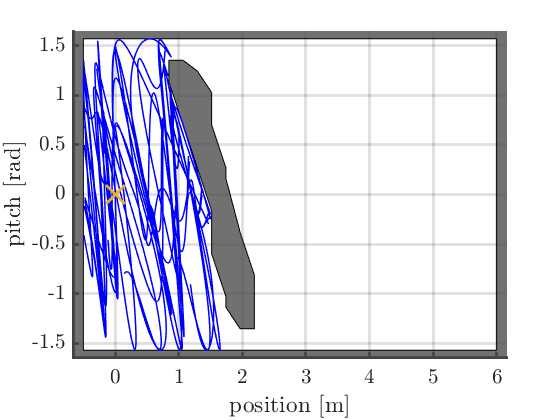


% Let's repeat with the some number of iterations
K = 500;
tree = kinodynamic_exploration(statespace, xI, K, lmp_func, forward_sim_func, x2y_func, distance_func);
% Plot Resultsstatespace
figure;
statespace.draw();
tree.draw('blue');
plotConfiguration(xI([1,3]));

### Planning

% Initialize RNG-Seed 
rng(2);
% Goal State
xG = [0; 0; 3.5; 0];
% Max number of iterations
K = 1000;
% Set goal-check-probability
goal_check_probability = 0.99;
% Let's go
tic;
[plan_flag, tree, UP, XP, nodelist] = kinodynamic_planning(statespace, xI, xG, K, lmp_func, forward_sim_func, x2y_func, distance_func, goal_check_probability);
toc;

Elapsed time is 53.233723 seconds.


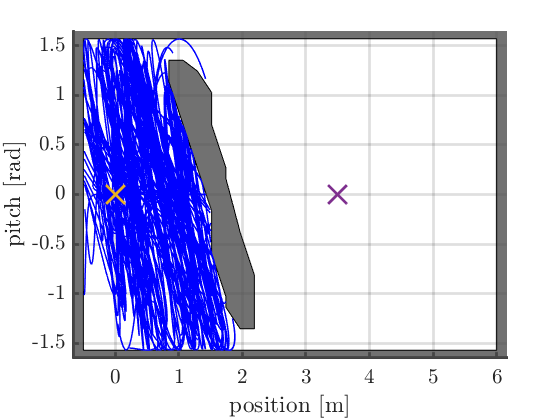


% Plot the results in C-space
figure;
statespace.draw();
tree.draw('blue');
if(plan_flag == true)
    plotStateTrajectoryInCSpace(XP);
end
plotConfiguration(xI([1,3]));
plotConfiguration(xG([1,3]));

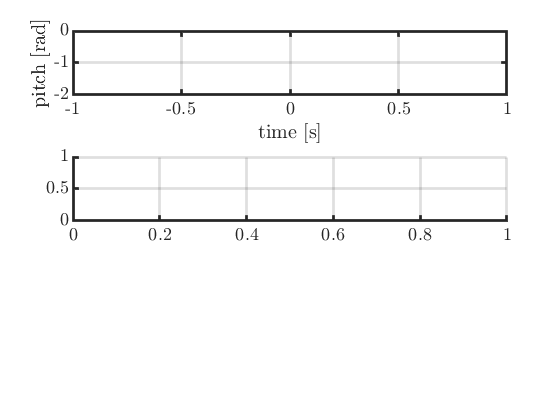

Index in position 1 exceeds array bounds (must not exceed 1).

Error in plotStateTrajectoriesOverTime (line 9)
    plot(t, X(3,:)); hold on;


% Plot the trajectories over time
figure;
plotStateTrajectoriesOverTime(XP, UP);

### Post Processing

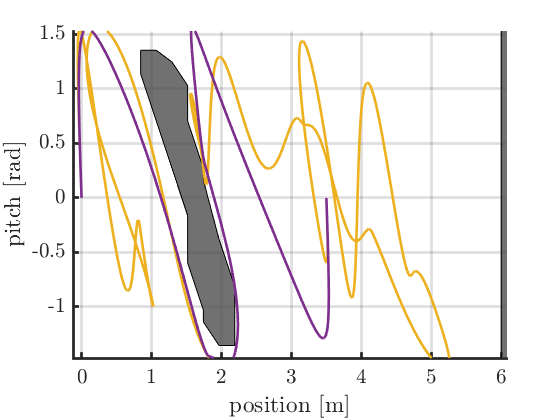

% Let's make the planned trajectory more beautiful
[Xnew, Unew] = trajectoryPostProcessing(xI, xG, XP, UP, statespace, lmp_func, forward_sim_func);
figure;
statespace.draw();
plotStateTrajectoryInCSpace(XP);
plotStateTrajectoryInCSpace(Xnew);

### Let's apply the planned input trajectory to the "ideal" dynamics used in planning

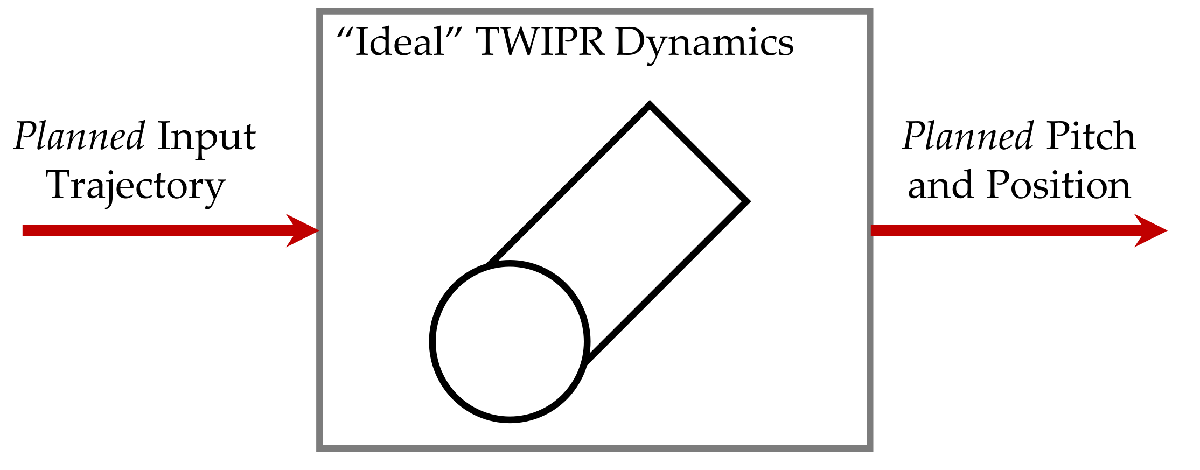

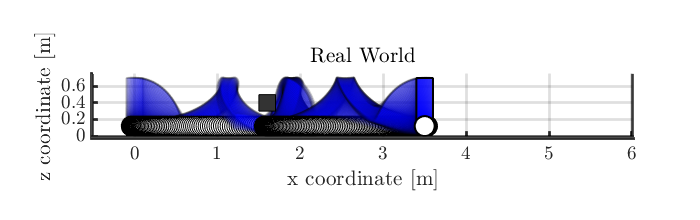

% Let's watch the planned trajectory in the real-world
load('1_Data/real_world.mat');
animate_movement_real_world(real_world, Xnew(1,:),Xnew(3,:));

### Let's apply the planned input trajectory to the real dynamics that differ from the ones used in planning

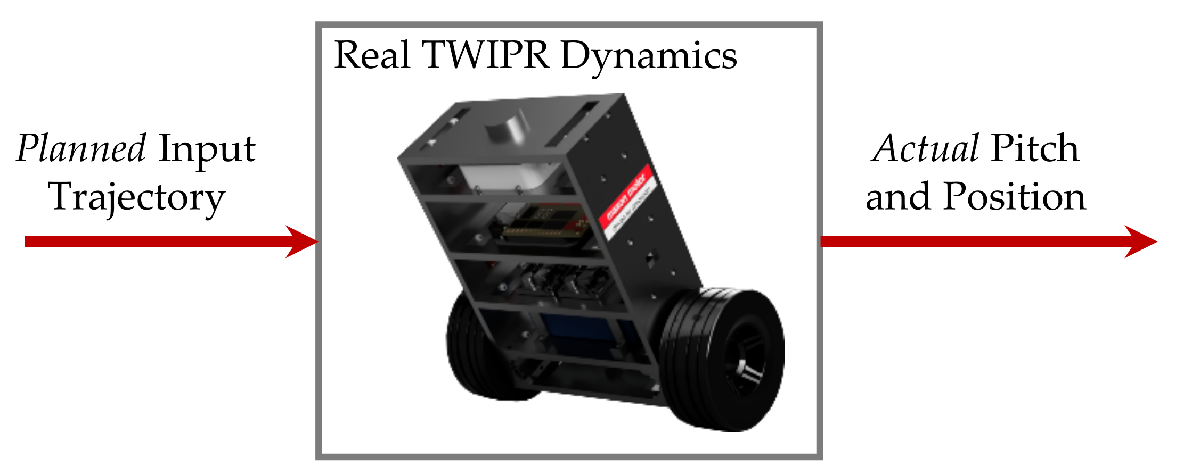

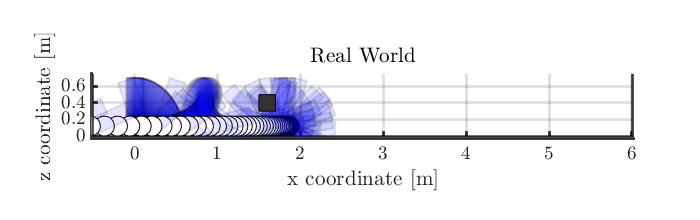

% Simulation
Xreal = simRealTWIPR(Unew);
% Let's watch the results in the real world
animate_movement_real_world(real_world, Xreal(1,:),Xreal(3,:));